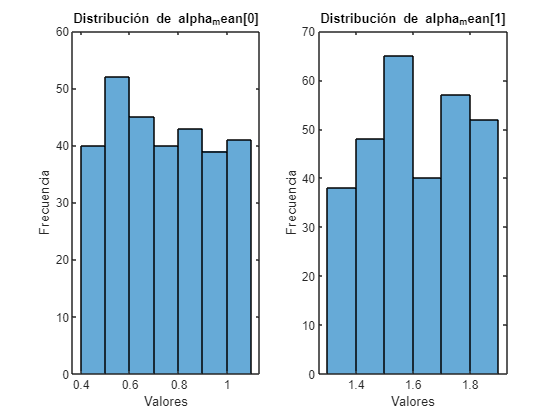

% Inicialización de alpha_mean con un rango modificado y comprobación de la diferencia
num_samples = 300;
alpha0 = zeros(num_samples, 1);
alpha1 = zeros(num_samples, 1);

for i = 1:num_samples
    % Inicialización de alpha_mean con un rango modificado y comprobación de la diferencia
    alpha_mean = round([0.4 + (rand * 0.7), 1.3 + (rand * 0.6)],2);
    while abs(alpha_mean(2) - alpha_mean(1)) < 0.2
        alpha_mean = round([0.4 + (rand * 0.7), 1.3 + (rand * 0.6)],2);
    end
    alpha0(i) = alpha_mean(1);
    alpha1(i) = alpha_mean(2);
end

figure;
subplot(1,2,1);
histogram(alpha0, 'BinEdges', 0.4:0.1:1.1);
title('Distribución de alpha_mean[0]');
xlabel('Valores');
ylabel('Frecuencia');

subplot(1,2,2);
histogram(alpha1, 'BinEdges', 1.3:0.1:1.9);
title('Distribución de alpha_mean[1]');
xlabel('Valores');
ylabel('Frecuencia');